依赖[统一实验分析作图v18.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Similar activity in MOp Learned_task_A and Transfer_task_B

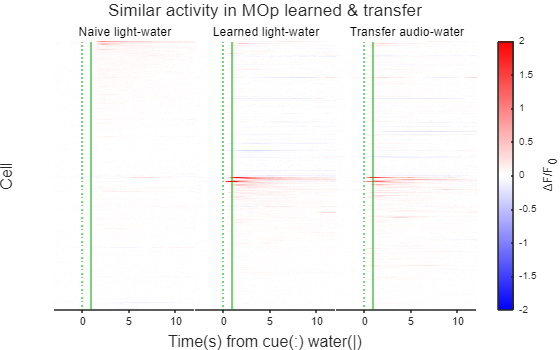

Fig=figure;
Layout=tiledlayout(2,2,TileSpacing='tight',Padding='tight');
Axes(1)=nexttile(Layout,1);
PcaLegend=TransferLearning.TransferSimilarity(TransferLearning.Flags.LightAudio|TransferLearning.Flags.PPT|TransferLearning.Flags.MOp,[1,2,5],PcaAx=Axes(1),CorrelationAx=nexttile(Layout,2));

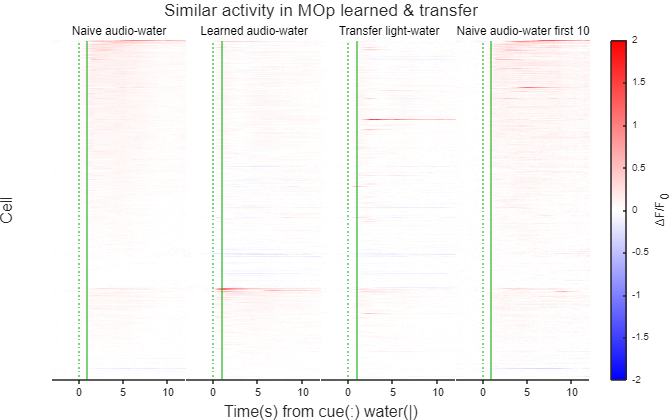

PcaLegend.Location='southeast';
Axes(2)=nexttile(Layout,3);
PcaLegend=TransferLearning.TransferSimilarity(TransferLearning.Flags.AudioLight|TransferLearning.Flags.PPT|TransferLearning.Flags.MOp,[1,2,5],HeatmapScale=MATLAB.Flags.Amplify,PcaAx=Axes(2),CorrelationAx=nexttile(Layout,4));

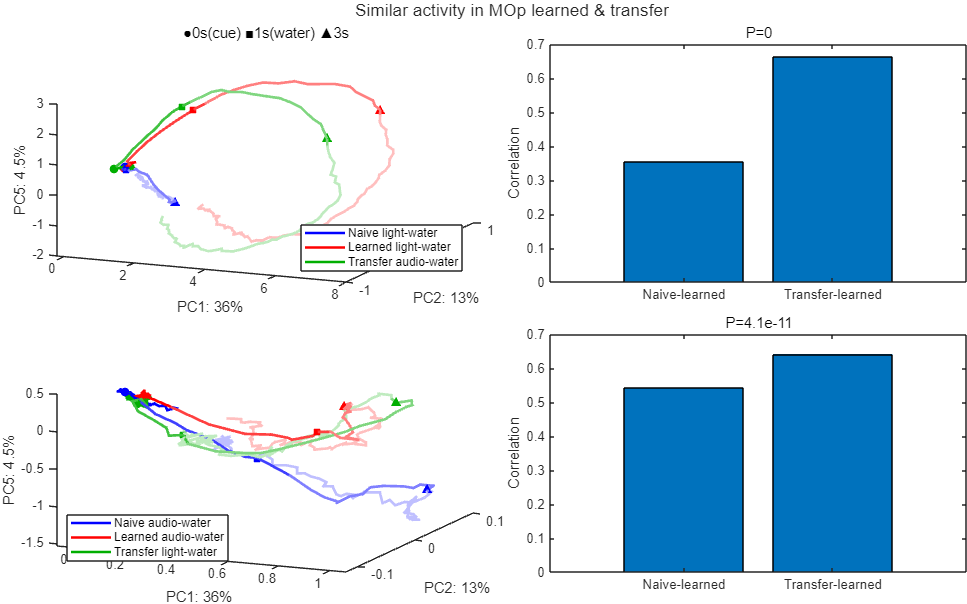

PcaLegend.Location='southwest';
title(Layout,'Similar activity in MOp learned & transfer');
title(Axes(1),'●0s(cue) ■1s(water) ▲3s')
xlabel(nexttile(Layout,2),'');
UniExp.PcaRotate(Axes,[36,13,37]);
MATLAB.Graphics.FigureAspectRatio(8,5,2,Fig);
print(Fig,TransferLearning.ProjectPath('迁移PCA和相关性.png'),'-dpng','-r300');